# Amplitude Modulation - A M

## Variables :


clear;
fm1 =400; %% Modulating signal frequency 3
fm2 =800; %%5
fc =3000; %% Carrier frequency 50
fs =20*fc;%% Sampling frequency 80
endpoint=0.1;
t =0:1/fs:endpoint; %% Time series index  0:1/fs:3
l = length(t); %% Length of vector t
i=(-l/2:1:l/2-1); %% frequency series index
Vm1=1; %%Peak amplitude of modulating signal
Vm2=2;
Vc = 5; %%Peak amplitude of carrier signal
%v_m = Vm1 *cos(2*pi*fm1*t); %%Modulating signal expression
v_m_1 = Vm1 *cos(2*pi*fm1*t);
v_m_2 = Vm2 *cos(2*pi*fm2*t);
v_m=v_m_1+v_m_2; %%multi-tone signal - two-tone signal

## Modulating and Carrier :

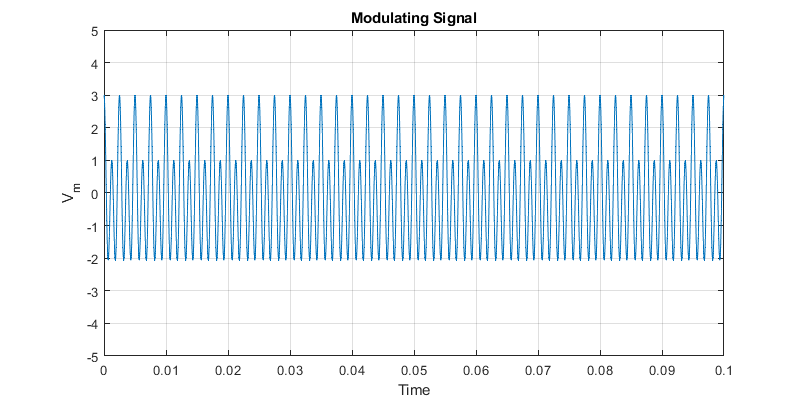

f1=figure;
plot(t,v_m);
xlabel("Time");
ylabel("V_m");
title("Modulating Signal");
set(f1,'Position',[0 0 800 400]);
grid on
ylim([-5.000 5.000]);

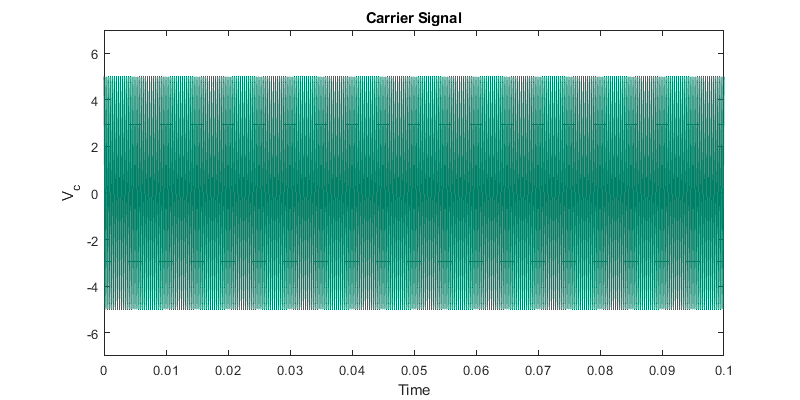


v_c=Vc*cos(2*pi*fc*t ); %%Carrier signal expression
f2 = figure;
set(gcf,'DefaultAxesColorOrder',colormap(summer(2)));
plot(t,v_c);
% axis[0 0.01 -6 6];
xlabel("Time");
ylabel("V_c");
title("Carrier Signal");
set(f2,'Position',[0 0 800 400]);
ylim([-(Vc+2) (Vc+2)]);

## A M Signal :

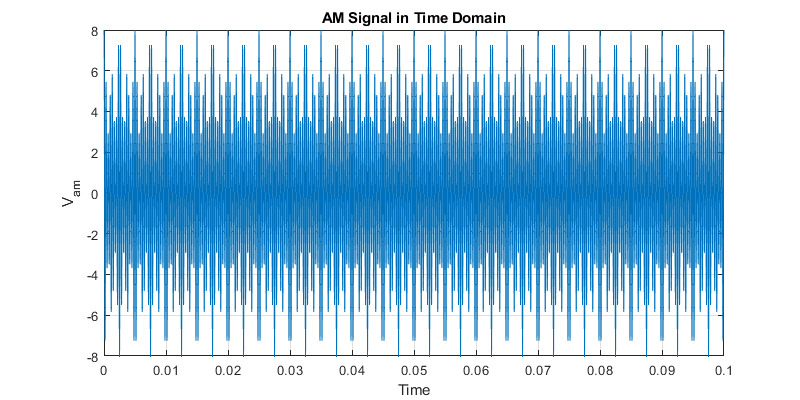


v_am=(Vc+v_m).*cos(2*pi*fc*t);%%multi-tone AM signal - two-tone AM signal
% subplot(3,1,3);
f3=figure;
plot(t,v_am);
xlabel("Time") ;
ylabel("V_a_m");
title("AM Signal in Time Domain");
set(f3,'Position',[0 0 800 400]);
grid on

%i=[-100:1:100]%% Generating indices along frequency axis

## A M Spectrum :

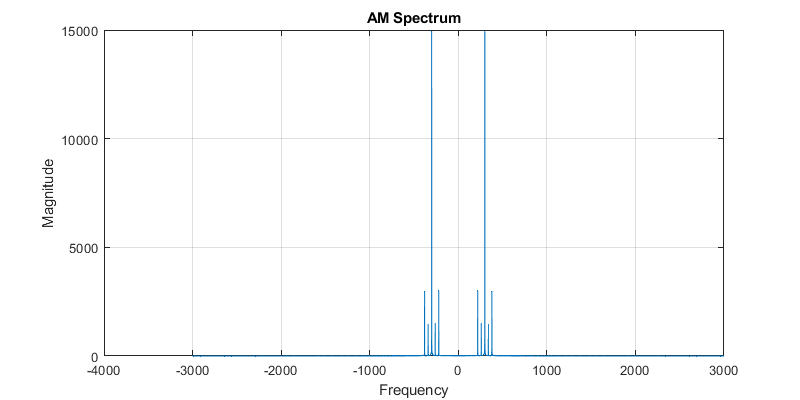


% subplot(3,1,1);
% i =(-fs/2:fs/l:fs/2-(fs/lS));
f4=figure;
fftVam=fftshift(fft(v_am));
plot(i,abs(fftVam)); %% FFT of AM signal
% plot(i,abs(fftshift(fft(v_am))));
title("AM Spectrum");
xlabel("Frequency");
ylabel("Magnitude");
set(f4,'Position',[0 0 800 400]);
grid on;

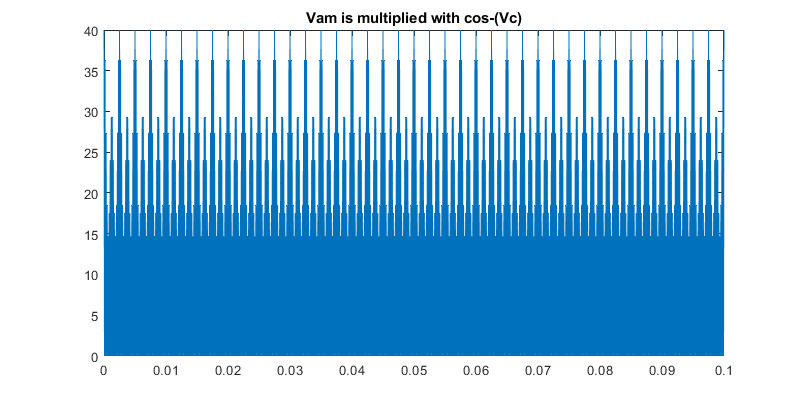



v_m_det=v_am.*v_c; %% Synchronous detection expression
plot(t,v_m_det);
title("Vam is multiplied with cos-(Vc)");

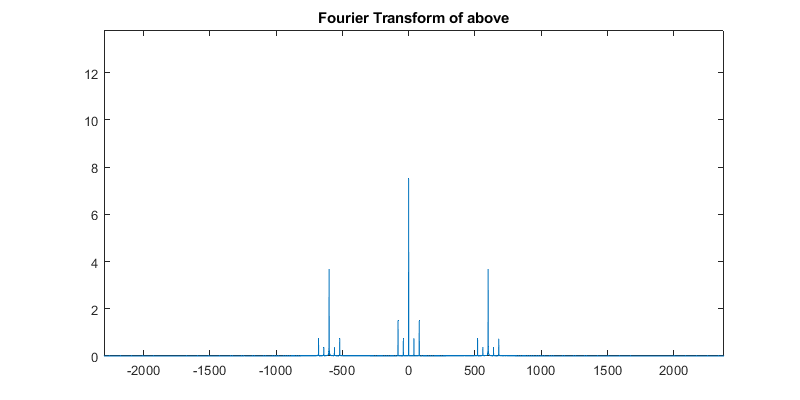

plot(i,abs(fftshift(fft(v_m_det)))/10000);
title("Fourier Transform of above");

xlim([-2299 2379])
ylim([0.0 13.8])

## Low Pass Filter :

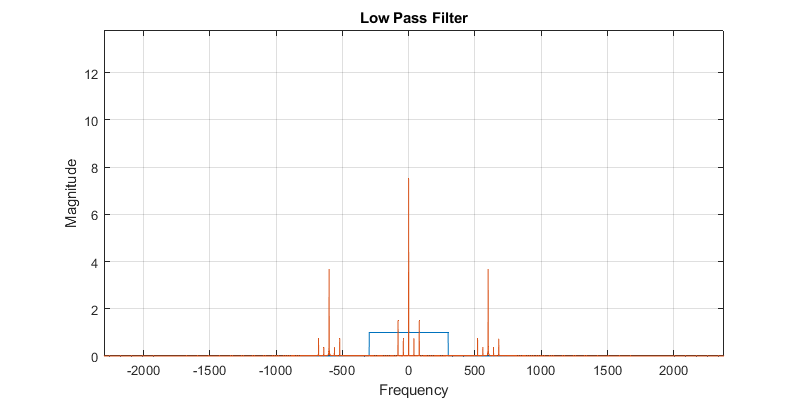


% lpf=[ones(1,10),zeros(1,l-4*fm1)]; %%LPF response
% lpf=[ones(1,4*fm2),zeros(1,l-4*fm2)]; %%LPF response
% a=(l-fm1)/2;
% a=round((l/2)-((fc+fm1)*0.1));
% b=round((l/2)-(l/2-a+fc*0.1)/2);
a=round(l/2);

tuner=4;

b=(2*fc*endpoint-tuner)/2;
% lpf=[ones(1,round(a)),zeros(1,l-round(a))]; %%LPF response
lpf=[zeros(1,a-b),ones(1,2*b),zeros(1,l-(2*b+a-b))]; %%LPF response
% lpf=[zeros(1,a-b),ones(1,b-3),zeros(1,6),ones(1,b-3),zeros(1,l-(2*b+a-b))]; %%LPF response

%subplot(3,1,3);
f6=figure;
plot(i,lpf);hold on
plot(i,abs(fftshift(fft(v_m_det)))/10000);
xlabel("Frequency");
ylabel("Magnitude");
title("Low Pass Filter");
set(f6,'Position',[0 0 800 400]);
xlim([-2299 2379])
ylim([0.0 13.8])
grid on;

## Demodulated Signal :

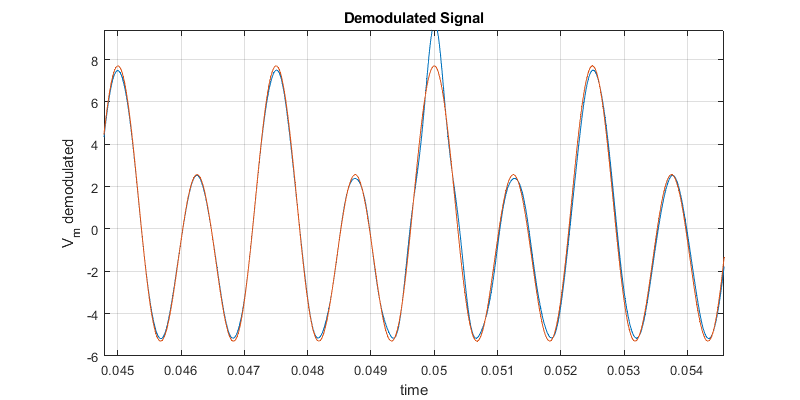


% v_m_demod_spec = fftVam.*lpf
v_m_demod_spec = (fftshift(fft(v_m_det))).*lpf ; %%Frequency domain profile of demodulated signal
% subplot(3,1,2);
f5=figure;
%% Final time domain plot of demodulated signal
% plot(t,-4.6-8.1+abs(ifftshift(ifft(v_m_demod_spec))));hold on
% plot(t,v_m*2.57); %% original signal-- red

plot(t,-12.504+abs(ifftshift(ifft(v_m_demod_spec))));hold on
plot(t,v_m*2.569); %% original signal-- red
xlabel("time");
ylabel("V_m demodulated") ;
title("Demodulated Signal");
set(f5,'Position',[0 0 800 400]);
grid on;


xlim([0.04478 0.05458])
ylim([-6.0 9.4])